# Lecture 14

## Exercise 7.7

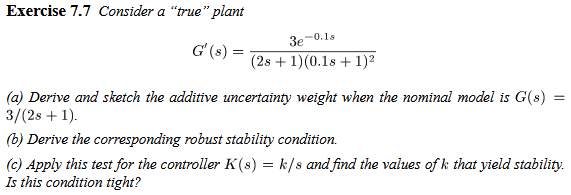

### a)

From slide 54 on additiveuncertainty: $G_p =G+W_a \Delta {\;}_a$

syms s

G_p = 3*exp(-0.1*s) / ((2*s + 1)*(0.1*s + 1)^2);
G = 3/(2*s + 1);

W_a = simplify(G_p - G)

$$W\_a = \frac{3\,{\mathrm{e}}^{-\frac{s}{10}}}{\left(2\,s+1\right)\,{\left(\frac{s}{10}+1\right)}^{2}}-\frac{3}{2\,s+1}$$

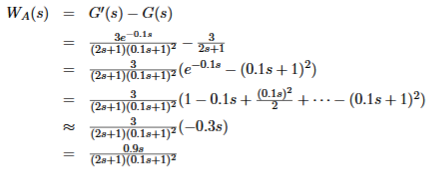

Idk why matlab can't do it, but this i the reduced fraction:

W_a = (0.9*s) / ((2*s + 1)*(0.1*s + 1)^2);

### b)

syms K

RS = simplify((W_a*K*inv(1 + G*K))) == 1

$$RS = \frac{90\,K\,s}{{\left(s+10\right)}^{2}\,\left(3\,K+2\,s+1\right)}=1$$

### c)

syms k omega
assume(k, "real")

T = (3*k) / (2*s^2 + s + 3*k);

eqn = T == G/W_a

$$eqn = \frac{3\,k}{2\,s^{2}+s+3\,k}=\frac{10\,{\left(\frac{s}{10}+1\right)}^{2}}{3\,s}$$

subs(eqn, s, 10)

$$ans = \frac{3\,k}{3\,k+210}=\frac{4}{3}$$

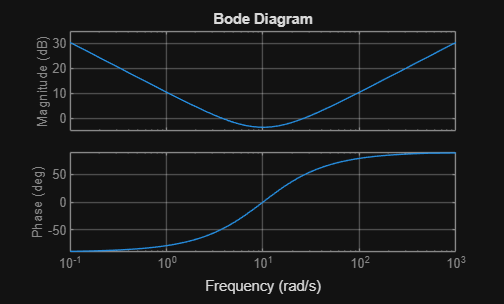

s = tf('s');
W_a = (0.9*s) / ((2*s + 1)*(0.1*s + 1)^2);
G = 3/(2*s + 1);
bode([G/W_a]); grid on;

## Exercise 2 from note

Page 54 from slides on additive uncertainty:

syms W_a K I G M w
s = tf('s');

G_nom = 10 / ((s)^2 + 0.2*(s) + 1);

M_Delta = M*w == W_a*K*inv(I + G*K)*w;

RS = W_a*K*inv(I + G*K) == 1

$$RS = \frac{K\,W_{a}}{\text{I}+G\,K}=1$$

RS/(K*inv(I + G*K))

$$ans = W_{a}=\frac{\text{I}+G\,K}{K}$$

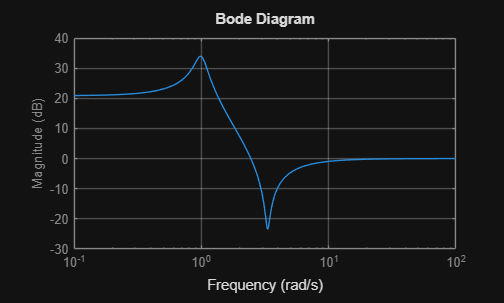

K = 1; I = 1;
W_a = (I + G_nom*K) / K;
bodemag(W_a)
grid on
hold off

Magnitude is in dB, but is correct.

## Exercise 3 from note

clear all;
clc;

syms W_a s

K = 1/s;

G_nom = (s + 1) / (s^2 + 0.2*s + 5);

G1 = G_nom + W_a;

%upper_bound = (G1 - G_nom)/G_nom
M = W_a*K*inv(1 + G_nom*K) == 1;
isolate(M, W_a)

$$ans = W_{a}=s\,\left(\frac{s+1}{s\,\left(s^{2}+\frac{s}{5}+5\right)}+1\right)$$

s = tf('s');
W_a = s*((s + 1)/(s*(s^2 + s/5 + 5)) + 1)


W_a =
 
  5 s^4 + s^3 + 30 s^2 + 5 s
  --------------------------
      5 s^3 + s^2 + 25 s
 
Continuous-time transfer function.
Model Properties


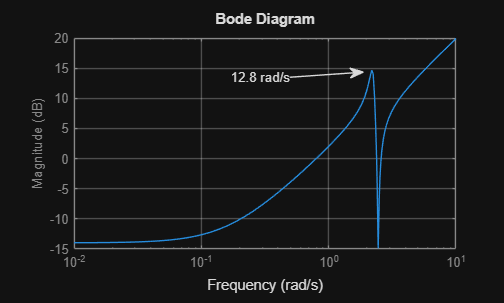

% getPeakGain(W_a) how is it calculated?
bodemag(W_a);
annotation("textarrow", [0.5746 0.7209], [0.745 0.762], "String", "12.8 rad/s")
grid on; hold off;

Here we can see that the system is unstable afte the peak at 2.18 rad/s

syms k s

W_m = k*(s + 10) / (s + 50)

$$W\_m = \frac{k\,\left(s+10\right)}{s+50}$$


G2 = G_nom*(1 + W_m)

$$G2 = \frac{\left(\frac{k\,\left(s+10\right)}{s+50}+1\right)\,\left(s+1\right)}{s^{2}+\frac{s}{5}+5}$$

s = tf('s');
k = (((s^2 + s/5 + 5) / (s + 1) - 1) * (s + 50)) / (s + 10)


k =
 
  5 s^3 + 246 s^2 - 180 s + 1000
  ------------------------------
        5 s^2 + 55 s + 50
 
Continuous-time transfer function.
Model Properties


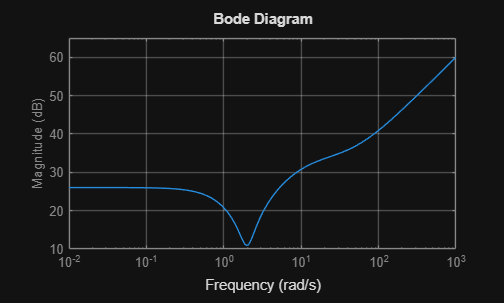

bodemag(k)
grid on; hold off;

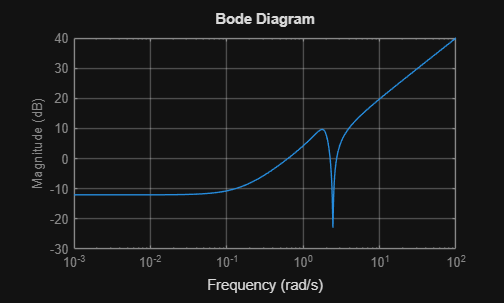

s = tf('s');
K = tf([1], [1 0]);
G_nom = tf([1 1], [1 0.2 5]);
T = (G_nom*K) / (1 + G_nom*K);
W_m = k*(s + 10) / (s + 50);
k = 1/(W_m*T);
bodemag(k)
grid on; hold off;


db2mag(-22.9)

ans = 0.0716